clear 
close all

## Model creation

### INITIAL MODEL

A =[-0.0175  0.173   -9.77    -5.63;
    -0.192   -1.09   -0.846   64.6;
    0        0        0       1;
    0.0081   -0.0738  0.0062  -1.9];
B =[-0.428;4.91;0;4.22];
C=eye(4);
D=[0;0;0;0];

Model=ss(A,B,C,D);
Model.StateName={'u_x','u_z','θ','q'};
Model.OutputName={'u_x','u_z','θ','q'}

Model =
 
  A = 
            u_x      u_z        θ        q
   u_x  -0.0175    0.173    -9.77    -5.63
   u_z   -0.192    -1.09   -0.846     64.6
   θ          0        0        0        1
   q     0.0081  -0.0738   0.0062     -1.9
 
  B = 
            u1
   u_x  -0.428
   u_z    4.91
   θ         0
   q      4.22
 
  C = 
        u_x  u_z    θ    q
   u_x    1    0    0    0
   u_z    0    1    0    0
   θ      0    0    1    0
   q      0    0    0    1
 
  D = 
        u1
   u_x   0
   u_z   0
   θ     0
   q     0
 
Continuous-time state-space model.



### Reference Model

Am =[-0.03   0.166    125.6     37.29;
     -0.052  -1.02    -1554.7   -427.82;
     0       0        0         1;
     0.128   -0.0142  -1335.49  -425.12];
Bm=[-0138.1;1584.2;0;1361.6];
Cm=eye(4);
Dm=[0;0;0;0];

ModelReference=ss(Am,Bm,Cm,Dm);
ModelReference.StateName={'u_x','u_z','θ','q'};
ModelReference.OutputName={'u_x','u_z','θ','q'}

ModelReference =
 
  A = 
            u_x      u_z        θ        q
   u_x    -0.03    0.166    125.6    37.29
   u_z   -0.052    -1.02    -1555   -427.8
   θ          0        0        0        1
   q      0.128  -0.0142    -1335   -425.1
 
  B = 
            u1
   u_x  -138.1
   u_z    1584
   θ         0
   q      1362
 
  C = 
        u_x  u_z    θ    q
   u_x    1    0    0    0
   u_z    0    1    0    0
   θ      0    0    1    0
   q      0    0    0    1
 
  D = 
        u1
   u_x   0
   u_z   0
   θ     0
   q     0
 
Continuous-time state-space model.



## Step responses

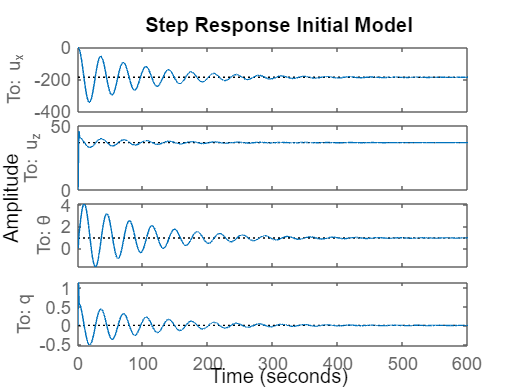

figure(1)
step(Model)
title("Step Response Initial Model")

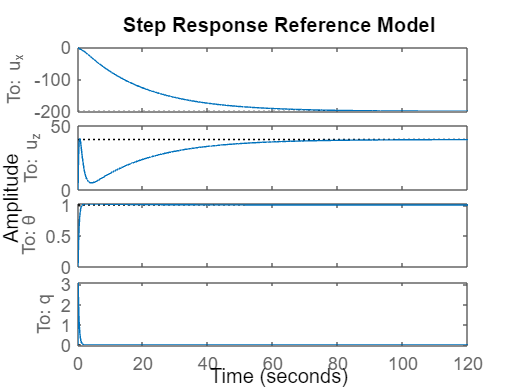

figure(2)
step(ModelReference)
title("Step Response Reference Model")

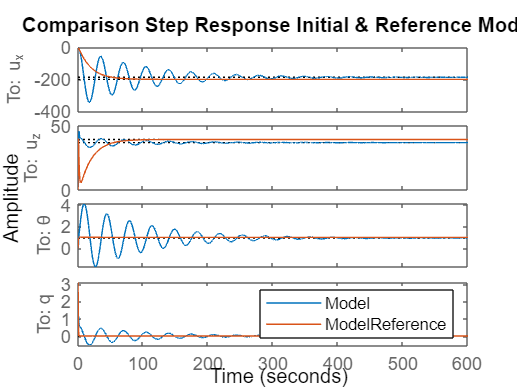

figure(3)
step(Model)
hold on
step(ModelReference)
hold off
legend
title("Comparison Step Response Initial & Reference Model")

## MRAC

### GAINS

Kr_i = B\Bm

Kr_i = 322.6504


Kx_i= (B)\(Am-A)

Kx_i =     0.0285    0.0142 -316.4669 -100.2891



ModelMRAC=ss(A+B*Kx_i, B*Kr_i, C,D);
ModelMRAC.StateName={'u_x','u_z','θ','q'};
ModelMRAC.OutputName={'u_x','u_z','θ','q'}

ModelMRAC =
 
  A = 
             u_x       u_z         θ         q
   u_x  -0.02969    0.1669     125.7     37.29
   u_z  -0.05219     -1.02     -1555    -427.8
   θ           0         0         0         1
   q      0.1283  -0.01384     -1335    -425.1
 
  B = 
            u1
   u_x  -138.1
   u_z    1584
   θ         0
   q      1362
 
  C = 
        u_x  u_z    θ    q
   u_x    1    0    0    0
   u_z    0    1    0    0
   θ      0    0    1    0
   q      0    0    0    1
 
  D = 
        u1
   u_x   0
   u_z   0
   θ     0
   q     0
 
Continuous-time state-space model.



### MRAC VS REFERENCE MODEL

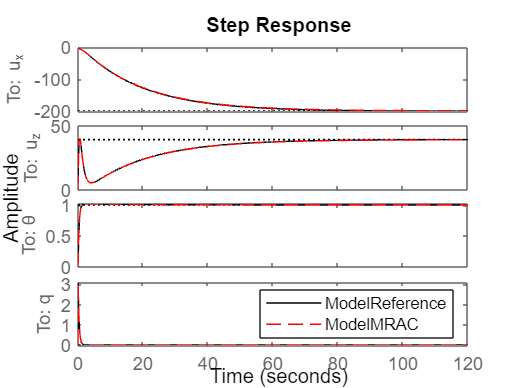

figure()
step(ModelReference,"k")
hold on
step(ModelMRAC,"r--")
hold off
legend


stepinfo(ModelMRAC)

ans = 4×1 struct array with fields:
    RiseTime
    TransientTime
    SettlingTime
    SettlingMin
    SettlingMax
    Overshoot
    Undershoot
    Peak
    PeakTime


### THETA

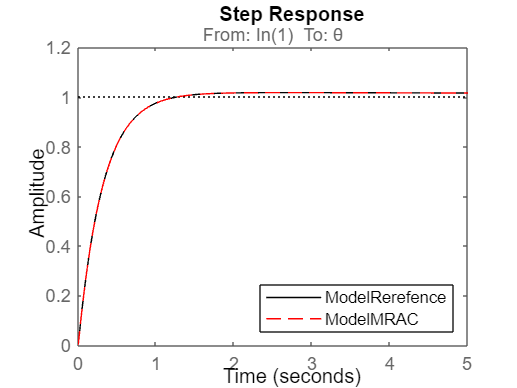

figure()
step(ModelReference(3,:),'k')
hold on
step(ModelMRAC(3,:),"r--")
hold off
legend("ModelRerefence","ModelMRAC",'Location','southeast')
xlim([0 5])

### PULSE TRAIN

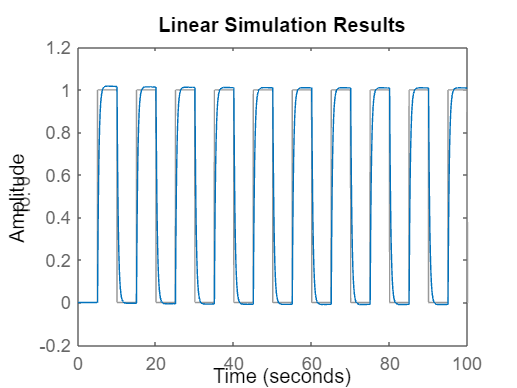

Ts = 0.05;
[u,t] = gensig("square",10,100,Ts); %tren de pulsos
lsim(ModelMRAC(3,:),u,t)

simInput = [t,u]

simInput =          0         0
    0.0500         0
    0.1000         0
    0.1500         0
    0.2000         0
    0.2500         0
    0.3000         0
    0.3500         0
    0.4000         0
    0.4500         0


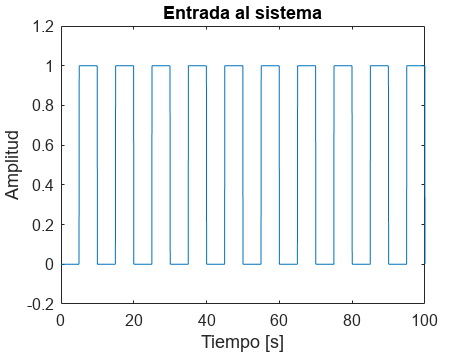


figure()
plot(t,u);
title('Entrada al sistema');
xlabel('Tiempo [s]');
ylabel('Amplitud');
ylim([-0.2 1.2])

## Simulación

data = sim("tarea3.slx",100)

data =   Simulink.SimulationOutput:

              MRACTheta: [1x1 timeseries] 
                  MRACq: [1x1 timeseries] 
                MRACu_x: [1x1 timeseries] 
                MRACu_z: [1x1 timeseries] 
                  input: [1x1 timeseries] 
          modelRefTheta: [1x1 timeseries] 
              modelRefq: [1x1 timeseries] 
            modelRefu_x: [1x1 timeseries] 
            modelRefu_z: [1x1 timeseries] 
                   tout: [6074x1 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


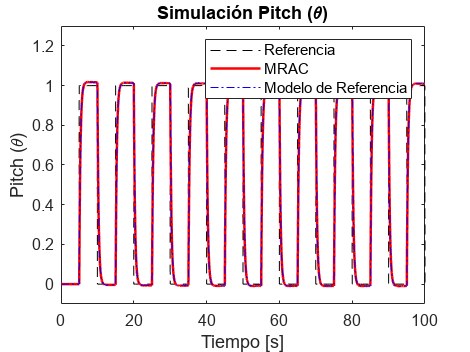


time = data.tout;

MRACTheta = data.MRACTheta.Data;
ModelRefTheta = data.modelRefTheta.Data;

figure()
plot(t,u,'k--');
hold on
plot(time,MRACTheta,'r','LineWidth',1.5);
plot(time,ModelRefTheta,'b-.');
hold off
title('Simulación Pitch (\theta)')
xlabel('Tiempo [s]');
ylabel('Pitch (\theta)');
ylim([-0.1 1.3])
legend('Referencia','MRAC','Modelo de Referencia')

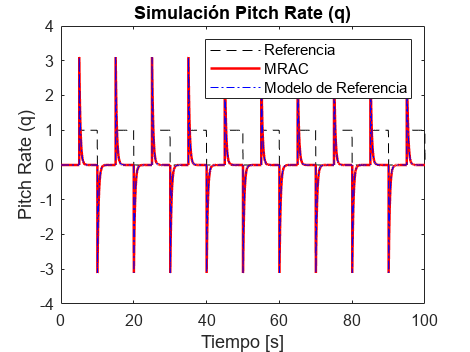



MRACq = data.MRACq.Data;
ModelRefq = data.modelRefq.Data;

figure()
plot(t,u,'k--');
hold on
plot(time,MRACq,'r','LineWidth',1.5);
plot(time,ModelRefq,'b-.');
hold off
title('Simulación Pitch Rate (q)')
xlabel('Tiempo [s]');
ylabel('Pitch Rate (q)');
legend('Referencia','MRAC','Modelo de Referencia')

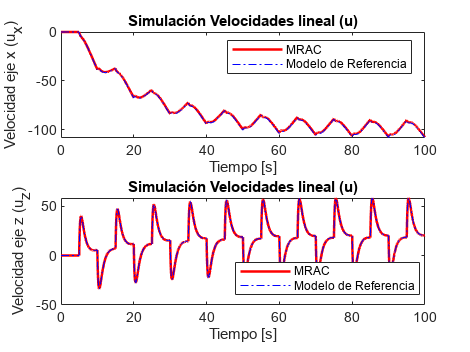


MRACu_x = data.MRACu_x.Data;
ModelRefu_x = data.modelRefu_x.Data;
MRACu_z = data.MRACu_z.Data;
ModelRefu_z = data.modelRefu_z.Data;

figure()
subplot(2,1,1)
plot(time,MRACu_x,'r','LineWidth',1.5);
hold on
plot(time,ModelRefu_x,'b-.');
hold off
xlabel('Tiempo [s]');
ylabel('Velocidad eje x (u_x)');
legend('MRAC','Modelo de Referencia')
title('Simulación Velocidades lineal (u)')
subplot(2,1,2)
plot(time,MRACu_z,'r','LineWidth',1.5);
hold on
plot(time,ModelRefu_z,'b-.');
hold off
xlabel('Tiempo [s]');
ylabel('Velocidad eje z (u_z)');
legend('MRAC','Modelo de Referencia','Location','best')
title('Simulación Velocidades lineal (u)')